# 홀로그램 계산코드 standard: Ver. 2022/09/16

## Include Library (함수 주소 지정)

clear all; close all; clc;  % clear all;변수 지우기   close all;화면 창 지우기    clc;명령 창 지우기
global Part1 Part2 Part3 Part4 Part5 nm um mm cm lambda lambda_ Ideal_angle_limit system_angle_limit Optimizer Iteration_num;
global k0 px py Nx Ny magnification_factor CPU_max_Nx GPU_max_Nx RGB_on RGB_switch complex_sum virtual_center DF_image_scale DF_intensity_scale;  %글로벌 변수명은 함부로 바꾸지 말 것

** addon 함수 파일들이 포함된 폴더 지정**

rootdir = 'D:\addon\'; addpath(genpath(rootdir));  % 모든 하위 폴더 추가
Hologram_code_history; %업데이트 내역 간단 정리한 파일
nm = 1e-9; um = 1e-6; mm = 1e-3; cm = 1e-2; % 단위 길이 정의
Filename_keyword = 'LFstudy'; %이 키워드에 맞춰서 파일명이 정해지도록 한다.
 

# %%% Part0. Basic info definition (시스템 정의) %%%

### 파트 0 실행하기

### **컴퓨터 성능 정의 : 추후 GPU/ 병렬 등등으로 업글 예정 **            

CPU_MEM_SIZE = 256;       GPU_MEM_SIZE = 11; %GB
CPU_max_Nx =   65000*sqrt(CPU_MEM_SIZE/128);     GPU_max_Nx =   16000*sqrt(GPU_MEM_SIZE/11);

### Part1: Calculation / Part2: Encoding / Part3: Reconstruction / Part4: LF model / Part5: Phase Optimizer

Part1 = "Import_LF";  % 불러올 것인지 계산할 것인지
Optimizer = "None"; Iteration_num = 50;
calculation_type = 'Fourier_plane';
Part2 = [false false true]; % (1) Mat 출력 (2) Bmp 출력 (3) Part3 연계 인코딩
Part3 = [true false]; % (1) 이미지 재생 (2) 동영상 재생
Part4 = [false false false false]; % (1) Calculate LF (2,3,4에 필수) (2) Export LF (3) View LF (4) Movie maker

image_center = 5*cm; %자주 쓰이는 값이므로 앞으로 가져왔음
propagation_type = 'ASM';
% ASM: 'Angular Spectrum Method' 물체가 가까울 경우에도 적용 가능 (expanded_transfer 함수 적용)
% Fresnel: 'Fresnel Approximation' 프레넬 근사조건 적용 (Fourier_plane)에서만 동작
% ARSS: 프레넬 근사조건 적용 + 엘리어싱 문제 개선 + Scaling/Shifting 연산 가능 (Fourier_plane)에서만 동작
% DSF: 'Double-step Fresnel Diffraction' ARSS Method + Fresnel Approximation Speckle 개선 (Fourier_plane)에서만 동작

### **사입사 조건 설정**

ref_cond = 'plane';  % 사입사 레퍼런스 설정
theta_ref = 0;  phi_ref = 90; % ref_cond = 'plane'; 일 때 사용. 단위는 degree (radian 아님) (광원 조건이므로 물체는 반대로 움직인다.)
point_ref = [0 0 50*mm];   % ref_cond = 'point'; 일 때 사용. 점광원 위치 [x00 y00 z00]

### 단색광 또는 RGB 여부 결정 

RGB_on = true;  % RGB_on = 0 이면 bmp 파일을 흑백으로 출력한다.
lambda_Mono = 521*nm;  % Mono -> gray 출력시 파장임
lambda_RGB  = [640 521 445]*nm; % RGB
RGB_switch  = [true true true]; % R G B 순서, 원하는 색만 골라서 시뮬돌린다
if RGB_on == 1 lambda_ = lambda_RGB;   disp(['This simulation has ', num2str(sum(RGB_switch)), ' wavelength(s)']);
else           lambda_ = lambda_Mono;  disp(['This simulation has 1 wavelength']); end 

This simulation has 3 wavelength(s)


### 픽셀 크기 & 픽셀 개수

pixel_pitch = 7.2*um; px = pixel_pitch; py = pixel_pitch; % 이미지 픽셀 크기
Nx = 2048; Ny = 2048; %픽셀 개수
magnification_factor = 1; %오목 렌즈 어레이 기법  (1이면 기본 계산)

### **랜덤 위상을 곱할 것인가**

random_phase_switch = true;  %Calculate_CGH or Calculate_CGH_movie 에 적용됨
% load('rand4096.mat');

# %%% Part 1 CGH를 불러오거나 계산 %%%

### 파트 1 실행하기

## (1) CGH를 불러오는 경우  "Import_CGH"

if strcmp(Part1, 'Import_CGH')
    filename = ['CGH_bmp_ASM' '.' 'bmp']; %파일명 + 확장자
    submain_Import_CGH;
end

## (2) CGH를 계산하는 경우  "Calculate_CGH"

if strcmp(Part1, 'Calculate_CGH')
    if RGB_on == 1; complex_sum_color = zeros(Ny,Nx,length(lambda_)); end
        switch calculation_type

**포인트 클라우드 방식**

            case 'point_cloud'
                read_object_switch = true;   % 1 파일형태 불러옴,  0 기본 example
                if read_object_switch
                    object_root = ["five_rings_4.stl"];   % 포인트 클라우드 경우, obj, stl, png 호환됨
                    point_reduction_factor = 1000;  % 점 개수를 이 배수만큼 줄인다 'read_object' 전용
                    z_num = 201; %z descrete 개수
                    system_angle_limit = 50; % 강제적으로 각주파수 성분을 해당 각도까지 제한함
                else                         % 기본 examples
                    image_type = 'circle';     % 포인트 클라우드 방식용/반지름1인 나선/모서리 1인 큐브/가로길이 1인 피라미드
                end
                image_reduction_factor = mm*0.2; % 입력 object의 크기 축소 배율
                rot_x = 0; rot_y =0; rot_z = 0;  % 포인트 데이타 회전변환 (degree)
                point_transfer_method = 7; % 1 original/ 2 xy데이타 픽셀화 / 3 중간에 플레인 하나 둬서 계산 / 4 2번에 z픽셀화 / 5 3번에 z픽셀화 / 6 미사용 / 7 공간주파수 분할 계산 /8 7번에 칼라점 구현
                submain_point_cloud_define; %세부 수정을 원할 경우 이 파일을 열어서 수정

**푸리에 플레인 방식 (image_center 값에서 각 면의 깊이 추가량 입력)**

            case 'Fourier_plane'
                image_center_ = image_center + [0 3       ]*cm;  % 각 이미지의 위치 지정
                object_root =                  ["작은지구.jpg" "달사진1.jpg" "" "" ""]; % 여러층인 경우 이렇게 배열로 넣는다. 푸리에 플레인 경우 png호환됨
                % 출력 이미지의 크기 비율 조정 (전체 영역 대비 가로세로 비율을 입력, Nx = 4096, px = 3.6um 일때, 14.75mm임)
                image_ratio_size = ceil([Ny*1 Nx*1]); image_ratio_size = image_ratio_size -mod(image_ratio_size ,2);

                %%%%%%%%%%% Double-Frensel 방식 전용 %%%%%%%%%%%%
                if strcmp(propagation_type,'DSF') 
                focus_center_x = [0 10 10]*mm;
                focus_center_y = [10 0 10]*mm; 
                
                virtual_center_min = ( max(max(abs(focus_center_x),abs(focus_center_y))) + Nx*px/2 ) / tand(asind(lambda_(3)/px/2)-0.0001); 
                disp(['Virtual center recommended to be longer than  ' num2str(virtual_center_min/cm) ' cm']); 
                virtual_center = 30*cm;
             
                theta_ref = atand( sqrt(focus_center_x.^2 + focus_center_y.^2) / virtual_center );
                phi_ref   = atand(focus_center_y./focus_center_x);
                DF_image_scale = [1 1 1]*(image_center/virtual_center - 1); %1인 경우가 image_center에서 최대 표현 이미지 크기임                
                DF_intensity_scale = [1 1 1];
                end                
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
                
                submain_Fourier_plane_define; %세부 수정을 원할 경우 이 파일을 열어서 수정
        end


## Hologram Generation - 본격적인 계산

    for lm_cnt = 1:1:length(lambda_)
        if RGB_switch(lm_cnt)
        lambda = lambda_(lm_cnt); prepare_lambda_k0_xx_yy_dfx_uu_vv; %k0,limit angle 정의, xx,yy,uu,vv,dfx 설정
        submain_Hologram_generation;
    if Part2(1); holo_save(filename_save,complex_sum,px,py,lambda,Nx,Ny,theta_ref,phi_ref,image_center); end  %% 추후 수정해야 함
    if RGB_on == 1; complex_sum_color(:,:,lm_cnt) = complex_sum; end
       end    
    end; 
    clear fmap;

## complex_sum 저장

    if RGB_on == 1; complex_sum = complex_sum_color; clear complex_sum_color; end
    if strcmp(propagation_type,'DSF')
    disp(['parameter:  virtual_center : ' num2str(virtual_center/cm) 'cm' ]);
    disp(['parameter:  DF_image_scale : ' num2str(image_center/virtual_center - 1) ' 배' ]);
    disp(['parameter:  theta_ref : ' num2str(theta_ref) ' degree' ]);
    end
end

## (3) 동영상 불러와서 CGH를 계산하는 경우 "Calculate_movie_CGH"

if strcmp(Part1, 'Calculate_movie_CGH')
      image_center_ = image_center + [0 10       ]*cm;  % 각 이미지의 위치 지정
      object_root =                  ["sample_video_carrot.avi" "sample_video_clock.avi" "" "" ""]; % 여러층인 경우 이렇게 배열로 넣는다. 
      image_ratio_size = ceil([Ny*0.4 Nx*0.4]); image_ratio_size =image_ratio_size -mod(image_ratio_size ,2);
      sample_type = '256_phase'; %No_save, 바이너리, 256 phase    
      crop_size = min([2160 3840],[Ny Nx]);  % crop_size = [2160 3840]; 
      movie_framerate = 2;    
      All_frames = false; % 모든 프레임 계산할 것인지?
      if All_frames == 0; Cal_frames = [1:2:24]; end % 계산하고픈 프레임들을 벡터로 넣는다 % end 는 쓰면안됨
      submain_Hologram_movie_generation_4_multiplane;      
end


## (4) LF를 불러와서 CGH를 계산하는 경우  "Import_LF"

if strcmp(Part1, 'Import_LF')
    filename = ['LF_bmp_LFstudy_uv_max_vnum8_vNN256_depth5_frame1' '.' 'bmp']; %파일명 + 확장자
    LF_calculation_type = "Hogel"
%     load("rand_table_LF_1.mat");  
%     image_center = 5*cm; %LF의 중심깊이
    submain_Import_LF;
end

LF_calculation_type = "Hogel"

  "Expanded transfer" calculation time : 0.511
  "Expanded transfer" calculation time : 0.195
  "Expanded transfer" calculation time : 0.194


## complex_sum 그려보기

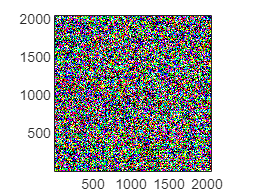

Part1_fig_On = true;
if Part1_fig_On;  figure('Name','Part1'); imagesc(angle(complex_sum)); axis xy; daspect([1 1 1]); colormap gray; end

# %%%%% Part 2 인코딩 %%%%%

### 파트 2 실행하기

### **Bmp 파일로 CGH 패턴 출력, 픽셀 너무 많으면 분할출력까지 자동**

crop_size = min([2160 3840],[Ny Nx]);  % crop_size = [2160 3840]; Ny Nx가 더 작다면 작은쪽을 따른다

if Part2(2)   % 0이면 No save와 동일함
    sample_type = '256_phase'; %No_save, 바이너리, 256 phase
    filename = ['CGH_bmp_' num2str(Filename_keyword) '_' num2str(px/um) 'px_' num2str(Nx) 'Nx_' num2str(image_center) 'depth' '.bmp'];
    hologram_export(complex_sum,filename,sample_type,crop_size);
end

### 시뮬레이션용 인코딩 (2022/01/03 : crop 방식 추가)

if Part2(3)   % 0이면 full complex와 동일함
    simulation_type = 'full_complex'; % 위상 방식
    crop_on = false;  dc_on = false; %crop_on : crop_size로 영역을 자른다,  %dc_on : 무회절광 추가한다
    scaling_factor = 1; % double-phase 인코딩 체커보드 픽셀 조정
    CGH_pattern = hologram_encoding(complex_sum,simulation_type,scaling_factor, crop_on, crop_size, dc_on);    
    if Nx >= 0.5*CPU_max_Nx; clear complex_sum;  end
else
    CGH_pattern = complex_sum;  if Nx >= 0.5*CPU_max_Nx; clear complex_sum;  end
end

## CGH_pattern 그려보기

Part2_fig_On = true;
if Part2_fig_On
    figure('Name','Part2');
    imagesc(angle(CGH_pattern));axis xy;daspect([1 1 1]);colormap gray;
end

# %%%% Part 3 계산된 CGH를 바탕으로 상 검증 %%%%

### 파트 3 실행하기

**재생파 조건 설정 & 재생 방식 결정**

recon_cond = 'same as reference';
theta_recon = 0;    phi_recon = 0;
point_recon = [0 0 50*mm]; 
submain_Part3_prepare_recon_source;

reconstruct_type = "Same as Part1";

**Part3 단일 CGH 이미지의 상출력을 위한 본격적인 계산 부분**

if Part3(1)   
    reconstructed_distance = image_center+0*cm;  % 위 부분을 조정 함으로서 위치 관찰 수정
    filter_diameter = 3*mm;  % Double_Fresnel 방식 전용
    submain_Reconstruct_CGH; %% 2022/04/05 이 부분 메인코드에서 복잡하지 않게 변경
else
    Reconstructed_GPU = CGH_pattern;
end

  "Expanded transfer" calculation time : 0.503
  "Expanded transfer" calculation time : 0.193
  "Expanded transfer" calculation time : 0.194
  "Part3: Reconstruct image plane" calculation time : 1.187


## Part 3 결과물 그려보기

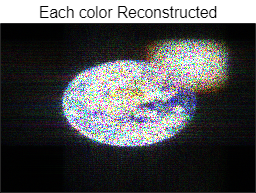

Part3_fig_On = true; save_fig = false;
Mono_From_RGB = false; % 재생상 Mono로 변환, color_type에 따라 plotting할 R,G,B 구별
color_type = "Red"; % 재생상에서 R,G,B 구별 'Red', 'Green', 'Blue'
Brightness_factor = 5;
if (Part3_fig_On) && Part3(1)  
    submain_Part3_draw;    
end

#### **Part3 CGH 동영상의 상출력을 위한 본격적인 계산 부분**

if Part3(2)
Obs_frames = Cal_frames; % 보고싶은 프레임들을 벡터로 넣는다 % 다 보고싶으면 [1:end] 를 넣는다
    Reconstructed_GPU_movie = zeros([size(CGH_pattern) length(Obs_frames)]);
    t2=clock; % 재생 파트 시간 계산
for t = 1: length(Obs_frames) 
        CGH_pattern = complex_sum_movie(:,:,:,t);        

        reconstructed_distance = image_center+3*cm;  % 위 부분을 조정 함으로서 위치 관찰 수정
        filter_diameter = 5*mm;  % Double_Fresnel 방식 전용
        submain_Reconstruct_CGH;
        

**Part 3 결과물 그려보기 (동영상 버전)**

Part3_fig_On = true;
    if (Part3_fig_On) && Part3(2)  
    submain_Part3_draw;    
    end 

        Reconstructed_GPU_movie(:,:,:,t) = Reconstructed_GPU;
    end

      Reconstructed_GPU = Reconstructed_GPU_movie;
    disp(['  "Part3: Reconstruct image plane for movie" calculation time : ' num2str(etime(clock,t2))]);
else
    Reconstructed_GPU_movie = CGH_pattern;
end

# %%%% Part 4 Light-field model 추출 및 관측 %%%%

### 파트 4 실행하기

#### Part3 결과의 공간주파수 도메인 확보

if strcmp(Part1,'Import_CGH') || strcmp(Part1,'Calculate_CGH'); Obs_frames = 1; end
if Part4(1)
    Reconstructed_GPU_FFTs = zeros([size(CGH_pattern) length(Obs_frames)]);
    for t = 1: length(Obs_frames)
        Reconstructed_GPU_FFTs(:,:,:,t) = Prepare_FFT_of_Part3(squeeze(Reconstructed_GPU(:,:,:,t)),theta_recon,phi_recon);
    end

## Light-field data 형성하기

   
    Fixed_value_LF = "uv_max"
    view_div_x = 8;  view_div_y = 8; %light_view 개수 %32
    LF_NN_divider = 8;  %16
    view_NN = Nx/LF_NN_divider; %FFT된 홀로그램(각도정보) 필터링 사이즈, 렌더링 데이타 해상도이기도 하다. view_NN 짝수여야 함

%     th_max = -asind(min(lambda_)*uu(1+view_NN/2));
%     th_max = asind(min(lambda_)/px/2)*0.95; % Ideal_angle_limits
    if strcmp(reconstruct_type,'Fresnel')
    px_LF = px_recon; % Ideal_angle_limits
    else   
    px_LF = px*[1 1 1]; end% Ideal_angle_limits

    LF_array_2D = zeros([(view_div_y/LF_NN_divider)*Ny (view_div_x/LF_NN_divider)*Nx 3 length(Obs_frames)]);
    for t = 1: length(Obs_frames)
        [LF_array th_max] = Light_field_calculation_4D(squeeze(Reconstructed_GPU_FFTs(:,:,:,t)),view_NN,view_div_x,view_div_y,Fixed_value_LF,px_LF);
        LF_array_2D(:,:,:,t) = LF_array_4Dto2D(LF_array);
    end

### Export Light Field

       
    LF_export_type = [true true]; %(1) Matfile_4D (2) Bmpfile_2D
    brightness_factor = 6;
    LF_array_2D_view = brightness_factor*uint8(255*rescale(abs(LF_array_2D)));
    if Part4(2)
    for t = 1: length(Obs_frames)
        frame_num = Obs_frames(t);   
        
        if LF_export_type(1)
            filename_LF = ['LF_mat_' num2str(Filename_keyword) '_' char(Fixed_value_LF) '_vnum' num2str(view_div_x) '_vNN' num2str(view_NN) '_depth' num2str(image_center/cm)];
            save([filename_LF '_full.mat'], 'LF_array','th_max','view_div_x','view_div_y','Fixed_value_LF','view_NN','px_LF','-v7.3','-nocompression');
        end

        if LF_export_type(2)
            filename_LF = ['LF_bmp_' num2str(Filename_keyword) '_' char(Fixed_value_LF) '_vnum' num2str(view_div_x) '_vNN' num2str(view_NN) '_depth' num2str(image_center/cm) '_frame' num2str(frame_num)];
            imwrite(squeeze(LF_array_2D_view(:,:,:,t)),[filename_LF '.bmp']);
            
            imwrite(squeeze(LF_array_2D_view(:,:,1,t)),[filename_LF '_R' '.bmp']);
            imwrite(squeeze(LF_array_2D_view(:,:,2,t)),[filename_LF '_G' '.bmp']);
            imwrite(squeeze(LF_array_2D_view(:,:,3,t)),[filename_LF '_B' '.bmp']);
            save([filename_LF '_supple.mat'], 'th_max','view_div_x','view_div_y','Fixed_value_LF','view_NN','px_LF');
        end
        end
    end

### View Light Field 

  
    if Part4(3)
        figure('Name','Light field');
        set(gcf,'Visible','on'); % 이미지 해상도가 너무 크면 라이브 스크립트에서는 이 문구 추가해야 함
        imagesc(rescale(squeeze(LF_array_2D_view(:,:,:,1))));   axis xy; %only draw for first frame
     end

### Movie recording

  
    if Part4(4)
%         movie_type = "Horizontal";   u_or_v_num = 0+view_div_x/2;
        vR = VideoWriter(['Movie_' Filename_keyword '_R.avi']); vR.FrameRate = 5; open(vR);
        vG = VideoWriter(['Movie_' Filename_keyword '_G.avi']); vG.FrameRate = 5; open(vG);
        vB = VideoWriter(['Movie_' Filename_keyword '_B.avi']); vB.FrameRate = 5; open(vB);
        for t_cnt = 1: length(Obs_frames)
            frameR = squeeze(LF_array_2D_view(:,:,1,t_cnt)); writeVideo(vR,frameR);
            frameG = squeeze(LF_array_2D_view(:,:,2,t_cnt)); writeVideo(vG,frameG);
            frameB = squeeze(LF_array_2D_view(:,:,3,t_cnt)); writeVideo(vB,frameB);
        end
        close(vR); close(vG); close(vB);
        
%     video_separation;
    end

end

# %%%% Part 5 Phase Optimizer (GS algorithm, SGD 등) %%%%

### 파트 5 실행하기